% Initial values
rng default;

% Load in Data
[qDate,qDemand,qPrice] = GetQueenslandData();

[saDate,saDemand,saPrice] = GetSouthAustraliaData();

[qPreviousDate,qPreviousDemand,qPreviousPrice] = OldQueenslandData();

[saPreviousDate,saPreviousDemand,saPreviousPrice] = OldSouthAustraliaData();

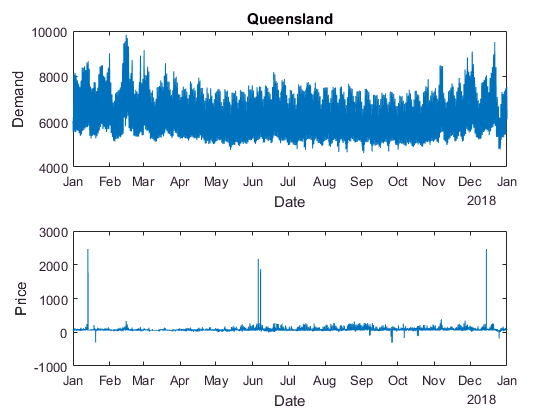

% Plot Data
PlotData(qDate,qDemand,qPrice,'Queensland');

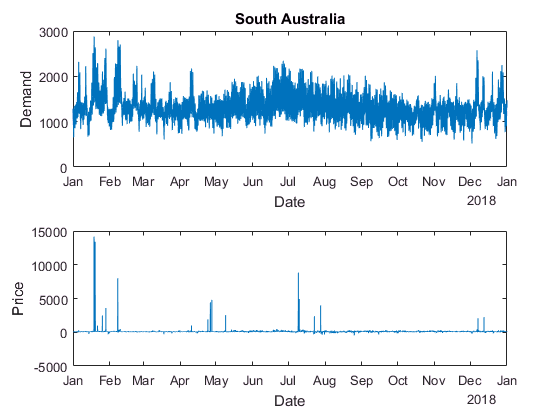


PlotData(saDate,saDemand,saPrice,'South Australia');

% Get Date arrays for models
dateArray = [qDate.Month,qDate.Day,qDate.Hour,qDate.Minute];

dateArrayPrevious = [qPreviousDate.Month,qPreviousDate.Day,qPreviousDate.Hour,qPreviousDate.Minute];

% Get Summer and Winter indexes
startSummerIndex = FindIndex('01-Dec-2018 00:00:00', qDate);
endSummerIndex = FindIndex('28-Feb-2018 23:30:00', qDate);

startWinterIndex = FindIndex('01-Jun-2018 00:00:00', qDate);
endWinterIndex = FindIndex('31-Aug-2018 23:30:00', qDate);

% Get Mean values for Queensland and South Australia Data in 2018

GetMeanSummer(qDemand, startSummerIndex, endSummerIndex, 'Queensland', 'Demand');

Queensland Mean Demand in Summer: 6670


GetMeanSummer(qPrice, startSummerIndex, endSummerIndex, 'Queensland', 'Price');

Queensland Mean Price in Summer: 76



GetMeanWinter(qDemand, startWinterIndex, endWinterIndex, 'Queensland', 'Demand');

Queensland Mean Demand in Winter: 6054


GetMeanWinter(qPrice, startWinterIndex, endWinterIndex, 'Queensland', 'Price');

Queensland Mean Price in Winter: 77



GetMeanSummer(saDemand, startSummerIndex, endSummerIndex, 'South Australia', 'Demand');

South Australia Mean Demand in Summer: 1370


GetMeanSummer(saPrice, startSummerIndex, endSummerIndex, 'South Australia', 'Price');

South Australia Mean Price in Summer: 120



GetMeanWinter(saDemand, startWinterIndex, endWinterIndex, 'South Australia', 'Demand');

South Australia Mean Demand in Winter: 1391


GetMeanWinter(saPrice, startWinterIndex, endWinterIndex, 'South Australia', 'Price');

South Australia Mean Price in Winter: 95


% Create models and test the training error
modelQLDDemand = fitlm(dateArray,qDemand);
modelQLDPrice = fitlm(dateArray,qPrice);

modelSADemand = fitlm(dateArray,saDemand);
modelSAPrice = fitlm(dateArray,saPrice);

CalculateError(qDemand, dateArray, modelQLDDemand, 'Queensland', 'Training', 'Demand');

Queensland Training error for Demand is: 511


CalculateError(qPrice, dateArray, modelQLDPrice, 'Queensland', 'Training', 'Price');

Queensland Training error for Price is: 18



CalculateError(saDemand, dateArray, modelSADemand, 'South Australia', 'Training', 'Demand');

South Australia Training error for Demand is: 217


CalculateError(saPrice, dateArray, modelSAPrice, 'South Australia', 'Training', 'Price');

South Australia Training error for Price is: 44


% Create models and test the testing error
[xTrain, xTest, yTrain, yTest] = CreateSplit( dateArray, qDemand, 0.5 );

Undefined function or variable 'dateArray'.

model = fitlm(xTrain,yTrain);
CalculateError( yTest, xTest, model, 'Queensland', 'Testing', 'Demand' );

[xTrain, xTest, yTrain, yTest] = CreateSplit( dateArray, qPrice, 0.5 );
model = fitlm(xTrain,yTrain);
CalculateError( yTest, xTest, model, 'Queensland', 'Testing', 'Price' );

[xTrain, xTest, yTrain, yTest] = CreateSplit( dateArray, saDemand, 0.5 );
model = fitlm(xTrain,yTrain);
CalculateError( yTest, xTest, model, 'South Australia', 'Testing', 'Demand' );

[xTrain, xTest, yTrain, yTest] = CreateSplit( dateArray, saPrice, 0.5 );
model = fitlm(xTrain,yTrain);
CalculateError( yTest, xTest, model, 'South Australia', 'Testing', 'Price' );

% Test how well a model can predict a value under a threshold across various models in QLD
[xTrain, xTest, yTrain, yTest] = CreateSplit( dateArray, qPrice, 0.5 );
model = fitlm(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'Queensland', 'linear');

linear Queensland TP: 3477 TN: 2283 FP: 911 FN: 2089



model = fitrgp(xTrain,yTrain, 'KernelFunction','ardsquaredexponential' );
CalculateThreshold( xTest, yTest, 75, model, 'Queensland', 'Gaussian process regression');

Gaussian process regression Queensland TP: 4499 TN: 2392 FP: 801 FN: 1068



model = fitrsvm(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'Queensland', 'SVM Linear');

SVM Linear Queensland TP: 4554 TN: 1637 FP: 1557 FN: 1012



model = fitrsvm(xTrain,yTrain, 'KernelFunction', 'gaussian');
CalculateThreshold( xTest, yTest, 75, model, 'Queensland', 'SVM Gaussian');

SVM Gaussian Queensland TP: 5028 TN: 2312 FP: 881 FN: 539



model = fitrlinear(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'Queensland', 'High deminsonal Linear Regression');

High deminsonal Linear Regression Queensland TP: 4513 TN: 1691 FP: 1503 FN: 1053



model = fitrtree(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'Queensland', 'Tree Regression');

Tree Regression Queensland TP: 4807 TN: 2515 FP: 679 FN: 759



model = fitrensemble(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'Queensland', 'Ensemble of learners for regression');

Ensemble of learners for regression Queensland TP: 4687 TN: 2506 FP: 688 FN: 879


% Test how well a model can predict a value under a threshold across various models in South Australia

[xTrain, xTest, yTrain, yTest] = CreateSplit( dateArray, saPrice, 0.5 );
model = fitlm(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 90, model, 'South Australia', 'Generalized linear regression' );

Generalized linear regression South Australia TP: 1704 TN: 2926 FP: 913 FN: 3217



model = fitrgp(xTrain,yTrain, 'KernelFunction','ardsquaredexponential' );
CalculateThreshold( xTest, yTest, 75, model, 'South Australia', 'Gaussian process regression');

Gaussian process regression South Australia TP: 1500 TN: 4765 FP: 832 FN: 1663



model = fitrsvm(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'South Australia', 'SVM Linear');

SVM Linear South Australia TP: 796 TN: 4941 FP: 656 FN: 2367



model = fitrsvm(xTrain,yTrain, 'KernelFunction', 'gaussian');
CalculateThreshold( xTest, yTest, 75, model, 'South Australia', 'SVM Gaussian');

SVM Gaussian South Australia TP: 1524 TN: 5230 FP: 367 FN: 1639



model = fitrlinear(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'South Australia', 'High deminsonal Linear Regression');

High deminsonal Linear Regression South Australia TP: 798 TN: 4931 FP: 666 FN: 2365



model = fitrtree(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'South Australia', 'Tree Regression');

Tree Regression South Australia TP: 2240 TN: 4893 FP: 704 FN: 923



model = fitrensemble(xTrain,yTrain);
CalculateThreshold( xTest, yTest, 75, model, 'South Australia', 'Ensemble of learners for regression');

Ensemble of learners for regression South Australia TP: 1877 TN: 3950 FP: 1647 FN: 1286


% Test how well a model can predict a value under a threshold across various models using previous year data in QLD
model = fitlm(dateArrayPrevious,qPreviousPrice);
CalculateThreshold( dateArray, qPrice, 75, model, 'Queensland', 'linear');

linear Queensland TP: 4415 TN: 4308 FP: 2164 FN: 6633



model = fitrgp(dateArrayPrevious,qPreviousPrice, 'KernelFunction','ardsquaredexponential' );
CalculateThreshold( dateArray, qPrice, 75, model, 'Queensland', 'Gaussian process regression');

Gaussian process regression Queensland TP: 7599 TN: 3935 FP: 2537 FN: 3449



model = fitrsvm(dateArrayPrevious,qPreviousPrice);
CalculateThreshold( dateArray, qPrice, 75, model, 'Queensland', 'SVM Linear');

SVM Linear Queensland TP: 9482 TN: 2008 FP: 4464 FN: 1566



model = fitrsvm(dateArrayPrevious,qPreviousPrice, 'KernelFunction', 'gaussian');
CalculateThreshold( dateArray, qPrice, 75, model, 'Queensland', 'SVM Gaussian');

SVM Gaussian Queensland TP: 8821 TN: 3208 FP: 3263 FN: 2228



model = fitrlinear(dateArrayPrevious,qPreviousPrice);
CalculateThreshold( dateArray, qPrice, 75, model, 'Queensland', 'High deminsonal Linear Regression');

High deminsonal Linear Regression Queensland TP: 9459 TN: 2110 FP: 4362 FN: 1589



model = fitrtree(dateArrayPrevious,qPreviousPrice);
CalculateThreshold( dateArray, qPrice, 75, model, 'Queensland', 'Tree Regression');

Tree Regression Queensland TP: 8437 TN: 3344 FP: 3128 FN: 2611



model = fitrensemble(dateArrayPrevious,qPreviousPrice);
CalculateThreshold( dateArray, qPrice, 75, model, 'Queensland', 'Ensemble of learners for regression');

Ensemble of learners for regression Queensland TP: 7538 TN: 3674 FP: 2798 FN: 3510


% Test how well a model can predict a value under a threshold across various models using previous year data in QLD
model = fitlm(dateArrayPrevious,saPreviousPrice);
CalculateThreshold( dateArray, saPrice, 75, model, 'South Australia', 'linear');

linear South Australia TP: 2331 TN: 8481 FP: 2689 FN: 4019



model = fitrgp(dateArrayPrevious,saPreviousPrice, 'KernelFunction','ardsquaredexponential' );
CalculateThreshold( dateArray, saPrice, 75, model, 'South Australia', 'Gaussian process regression');

Gaussian process regression South Australia TP: 3807 TN: 7128 FP: 4043 FN: 2542



model = fitrsvm(dateArrayPrevious,saPreviousPrice);
CalculateThreshold( dateArray, saPrice, 75, model, 'South Australia', 'SVM Linear');

SVM Linear South Australia TP: 5247 TN: 4574 FP: 6597 FN: 1102



model = fitrsvm(dateArrayPrevious,saPreviousPrice, 'KernelFunction', 'gaussian');
CalculateThreshold( dateArray, saPrice, 75, model, 'South Australia', 'SVM Gaussian');

SVM Gaussian South Australia TP: 4386 TN: 5835 FP: 5336 FN: 1963



model = fitrlinear(dateArrayPrevious,saPreviousPrice);
CalculateThreshold( dateArray, saPrice, 75, model, 'South Australia', 'High deminsonal Linear Regression');

High deminsonal Linear Regression South Australia TP: 5271 TN: 4689 FP: 6483 FN: 1077



model = fitrtree(dateArrayPrevious,saPreviousPrice);
CalculateThreshold( dateArray, saPrice, 75, model, 'South Australia', 'Tree Regression');

Tree Regression South Australia TP: 4164 TN: 6168 FP: 5002 FN: 2186



model = fitrensemble(dateArrayPrevious,saPreviousPrice);
CalculateThreshold( dateArray, saPrice, 75, model, 'South Australia', 'Ensemble of learners for regression');

Ensemble of learners for regression South Australia TP: 3840 TN: 6654 FP: 4518 FN: 2508
